close all;
clear; clc;

fileID = fopen('saved_points.txt');

x = {};
y = {};

current_frame = 1;

while 1
    line_of_text = fgetl(fileID);
    if line_of_text == -1
        break
    end
    
    x{current_frame} = [];
    y{current_frame} = [];
    
    current_point = 1;
    
    while 1
        line_of_text = fgetl(fileID);
        if line_of_text(1) == 'E'
            break
        end
        numeric_data = str2num(line_of_text);
        x{current_frame}(current_point) = numeric_data(1);
        y{current_frame}(current_point) = numeric_data(1);
        
        current_point = current_point + 1;
    end
    
    current_frame = current_frame + 1;
end

fclose(fileID);

x

x = 1×126 cell array
    {1×109 double}    {1×106 double}    {1×105 double}    {1×104 double}    {1×103 double}    {1×103 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×99 double}    {1×100 double}    {1×100 double}    {1×105 double}    {1×103 double}    {1×106 double}    {1×105 double}    {1×106 double}    {1×105 double}    {1×104 double}    {1×100 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×103 double}    {1×103 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×103 double}    {1×99 double}    {1×99 double}    {1×103 double}    {1×100 double}    {1×101 double}    {1×102 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×101 double}    {1×100 double}    {1×99 

y

y = 1×126 cell array
    {1×109 double}    {1×106 double}    {1×105 double}    {1×104 double}    {1×103 double}    {1×103 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×99 double}    {1×100 double}    {1×100 double}    {1×105 double}    {1×103 double}    {1×106 double}    {1×105 double}    {1×106 double}    {1×105 double}    {1×104 double}    {1×100 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×103 double}    {1×103 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×102 double}    {1×103 double}    {1×99 double}    {1×99 double}    {1×103 double}    {1×100 double}    {1×101 double}    {1×102 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×101 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×100 double}    {1×101 double}    {1×100 double}    {1×99 


mean_curvatures = zeros(length(x));

for i = 1:length(x)
    frame_x = x{i};
    frame_y = y{i};
    
    z = [frame_x frame_y];
    windowSize = 10;
    halfWidth = floor(windowSize/2);%half window size
    curvatures = zeros(size(frame_x));
    
    for k = halfWidth+1 : length(frame_x) - halfWidth
        theseX = frame_x(k-halfWidth:k+halfWidth);   % 19 element of x
        theseY = frame_y(k-halfWidth:k+halfWidth);   % 19 elemebt of y
        % Get a fit.
        coefficients = polyfit(theseX, theseY, 2);
        % Get the curvature
        curvatures(k) = coefficients(1);
        %   xc(k) = x(k)
        %   yc(k) = y(k)  
    end
    
    curvatures(abs(curvatures) > 20) = 0;
    curvatureMean = mean(curvatures);
    
    mean_curvatures(i) = curvatureMean;
    
end

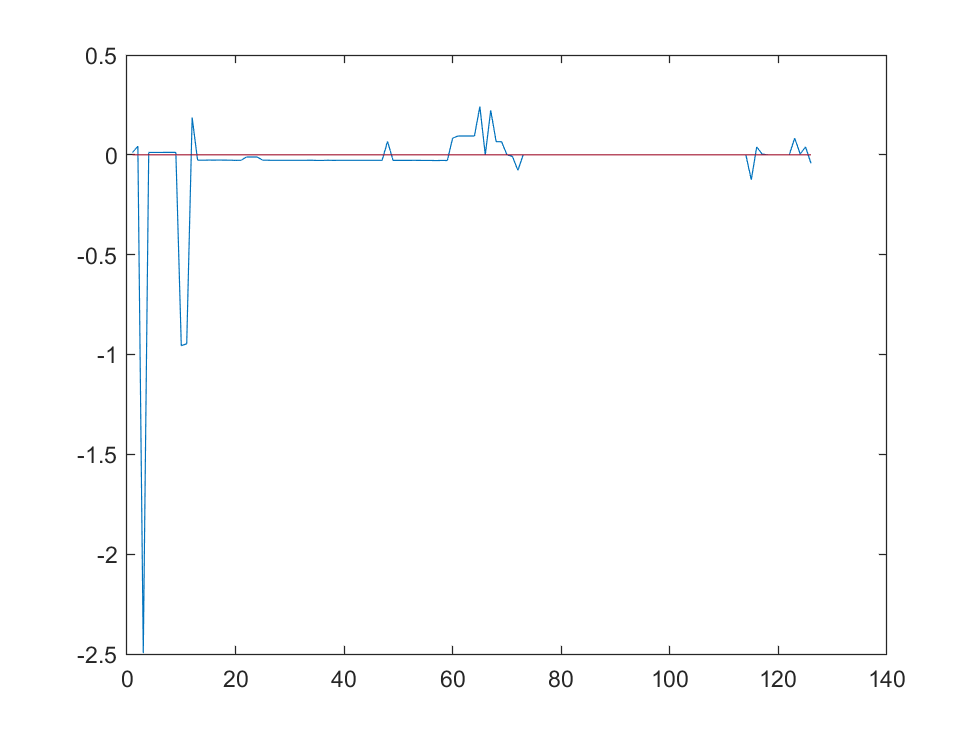


plot(mean_curvatures)



%x = transpose([37, 38, 39, 39, 40, 40, 41, 42, 43, 42, 41, 40, 39, 38, 37, 36, 35, 34, 33, 32, 31, 30, 29, 28, 27, 26, 27, 28, 29, 28, 27, 26, 25, 24, 23, 22, 21, 20, 19, 18, 17, 16, 15, 15, 15, 16, 16, 16, 16, 16, 15, 16, 16, 16, 16, 17, 17, 18, 19, 20, 21, 22, 23, 24, 25, 26, 27, 28, 29, 30, 31, 32, 33, 34, 35, 36, 37, 38, 39, 40, 41, 42, 43, 44, 45, 45, 44, 44, 44, 43, 43, 43, 43, 43, 42, 41, 41, 42, 43, 44, 44, 44, 43, 42, 42, 41, 40, 39, 38])
%y = transpose([12, 13, 14, 15, 16, 17, 18, 18, 19, 20, 20, 20, 19, 18, 17, 16, 16, 16, 15, 15, 15, 16, 16, 16, 16, 15, 14, 14, 13, 13, 13, 14, 14, 14, 14, 14, 15, 15, 15, 15, 15, 16, 16, 17, 18, 19, 20, 21, 22, 23, 24, 25, 26, 27, 28, 29, 30, 30, 31, 31, 32, 32, 33, 33, 33, 33, 33, 33, 33, 33, 33, 33, 33, 33, 33, 32, 32, 32, 32, 32, 32, 32, 32, 32, 32, 31, 30, 29, 28, 27, 26, 25, 24, 23, 24, 23, 22, 21, 21, 21, 20, 19, 18, 17, 16, 15, 14, 13, 13])
%z = [x y];
%windowSize = 10;
%halfWidth = floor(windowSize/2);%half window size
%curvatures = zeros(size(x));

%for k = halfWidth+1 : length(x) - halfWidth
%  theseX = x(k-halfWidth:k+halfWidth);   % 19 element of x
%  theseY = y(k-halfWidth:k+halfWidth);   % 19 elemebt of y
  % Get a fit.
%  coefficients = polyfit(theseX, theseY, 2);
  % Get the curvature
%  curvatures(k) = coefficients(1);
%   xc(k) = x(k)
%   yc(k) = y(k)  
%end
% Get rid of ridiculous curvatures (straight line segments).
%curvatures(abs(curvatures) > 20) = 0;
%curvatures = flip(curvatures)
%
%plot(x, curvatures, 'b-');
% hold on
%plot(y, curvatures, 'r-');
%plot3(x,y,curvatures)
%min_Cur = min(curvatures)
%
%max_Cur = max(curvatures)
%[L W] = size(curvatures);
%

%curvatureMean = mean(curvatures)

% CurCur = curvatures;
% for i = 1 :L
%     for j = 1 : W
%         if CurCur (i,j) < 0  %negative values
%            CurCur (i,j) =  CurCur (i,j) +(abs(min_Cur))
%         elseif CurCur (i,j) > 0  %positive values
%             CurCur (i,j) =  CurCur (i,j) + 100
%         end
%     end
% end
% curvatures = CurCur;